# **MUSIC DOA Estimation**

南京航空航天大学 电子工程系 张小飞

注释学习笔记：qwe14789cn@gmail.com

初始化

clc;
clear;

参数设置

rng(2018);
N = 8;                                              % 阵列数量
lambda = 1;                                         % 波长
delta_d = lambda/2;                                 % 阵列间距 
d=0:delta_d:(N-1)*delta_d;                          % 阵列坐标
iwave = 3;                                          % 3个信号源
theta = [10 30 60];                                 % 波达角度
snr = 20;                                           % 信噪比
n = 500;                                            % 信号采样快拍数
A=exp(-1i*2*pi./lambda.*d.'*sind(theta));           % 这个是信号的导向矢量
%--------------------------------------------------------------------------------
%   注意这里发现一个问题，信号是不相关的，如果是相关的会有什么样的结果？
%   雷达这里要怎么办？如果回波是相关的话？
%--------------------------------------------------------------------------------
S=randn(iwave,n);                                   % 构造3个发射波形，500个快拍，并且不相关

X=A*S;                                              % 阵元接收到的信号理论上如下，带相位偏移
X1=awgn(X,snr,'measured');                          % 实际上各个阵列接收到的信号带有高斯白噪声
Rxx=X1*X1'/n;                                       % 得到信号的协方差矩阵
[EV,D]=eig(Rxx);                                    % 计算协方差矩阵的特征向量，特征值
EVA=diag(D);                                        % 得到矩阵的对角元素
[EVA,I]=sort(EVA);                                  % 排列并得到序号
EVA=flipud(EVA);                                    % 这你妈有个叼用？
EV=fliplr(EV(:,I));                                 % 得到新的对应的特征值

MUSIC搜索

angle_d = zeros(361,1);                             % 搜索角度
SP      = zeros(361,1);                             % 输出缓冲区
L = iwave;
En=EV(:,L+1:N);
for idx = 1:361
    angle_d(idx)=(idx-181);
    a=exp(-1i*2*pi./lambda.*d*sind(angle_d(idx))).';% 实际上这个就是搜索的相位 也就是fft的相位积累
    
    SP(idx) = (a'*a)/(a'*(En*En')*a);
    SP(idx) = 1 ./ (a'*(En*En')*a);
end

得到伪谱

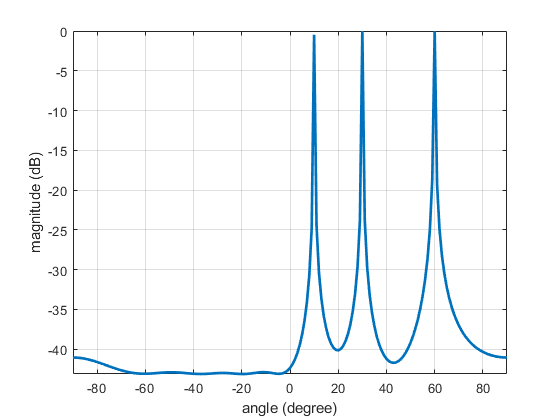

SP_A=abs(SP);
SP_Amax=max(SP_A);
SP_dB=10*log10(SP_A/SP_Amax);
h=plot(angle_d,SP_dB);
set(h,'Linewidth',2)
xlabel('angle (degree)')
ylabel('magnitude (dB)')
axis([-90 90 -inf 0])
set(gca, 'XTick',(-180:20:180))
grid on